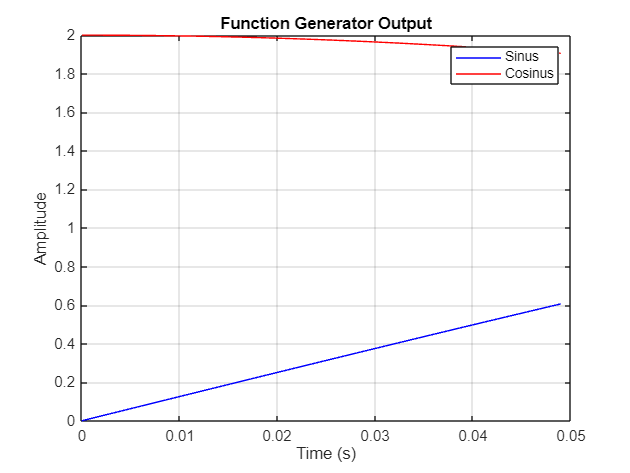

Data from C:\Users\rocks\OneDrive\Desktop\Info\output2.csv visualized successfully.


% MATLAB Visualization Script

% Prompt user to input the CSV filename
filename = input('Enter the CSV filename to load: ', 's');


% Validate file existence
if ~isfile(filename)
    fprintf('The file %s does not exist. Please provide a valid file path.\n', filename);
    return;
end

% Load the data
try
    data = readmatrix(filename);
    if size(data, 2) < 3
        error('InvalidFormat');
    end
    time = data(:, 1);  % First column: Time
    sinValues = data(:, 2); % Second column: Sin values
    cosValues = data(:, 3); % Third column: Cos values

    % Plot the data
    figure;
    plot(time, sinValues, 'b', 'DisplayName', 'Sinus');
    hold on;
    plot(time, cosValues, 'r', 'DisplayName', 'Cosinus');
    hold off;

    % Add labels, title, and legend
    xlabel('Time (s)');
    ylabel('Amplitude');
    title('Function Generator Output');
    legend show;
    grid on;

    fprintf('Data from %s visualized successfully.\n', filename);
catch ME
    if strcmp(ME.identifier, 'InvalidFormat')
        fprintf('The file %s does not contain the required data format. Ensure it has at least three columns.\n', filename);
    else
        fprintf('An unexpected error occurred while processing the file %s. Check the file and try again.\n', filename);
    end
end
